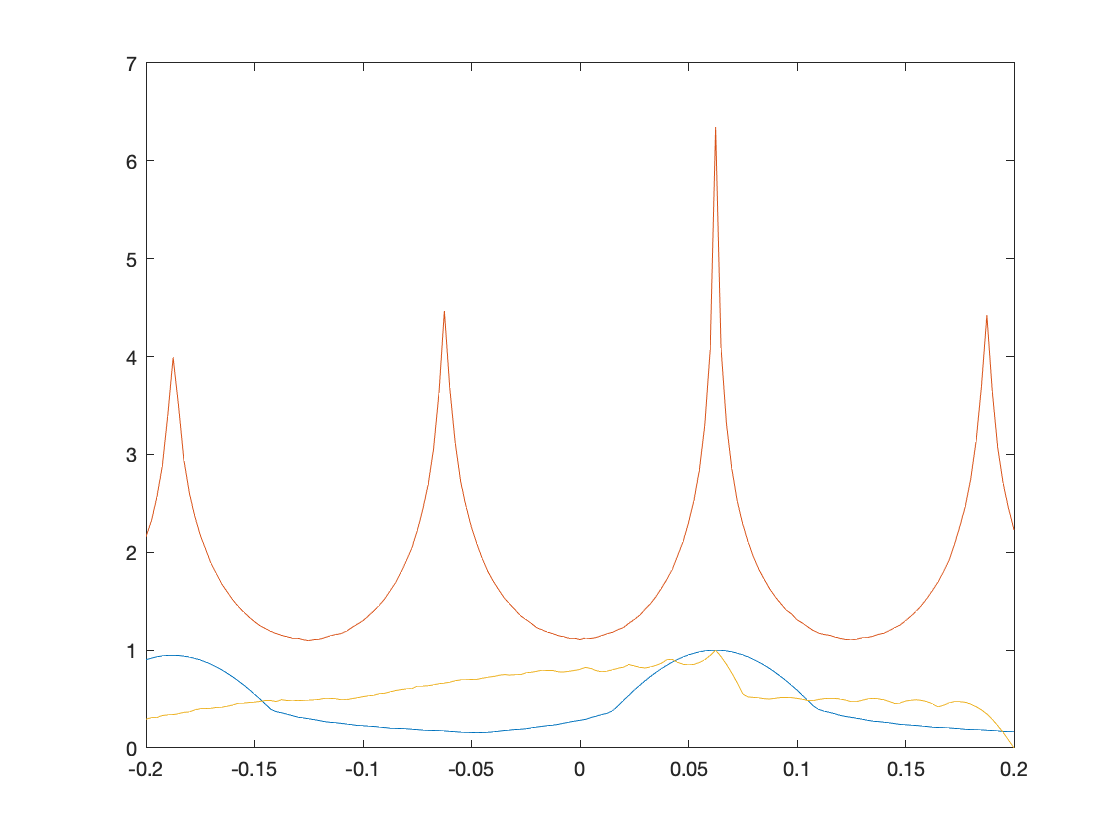

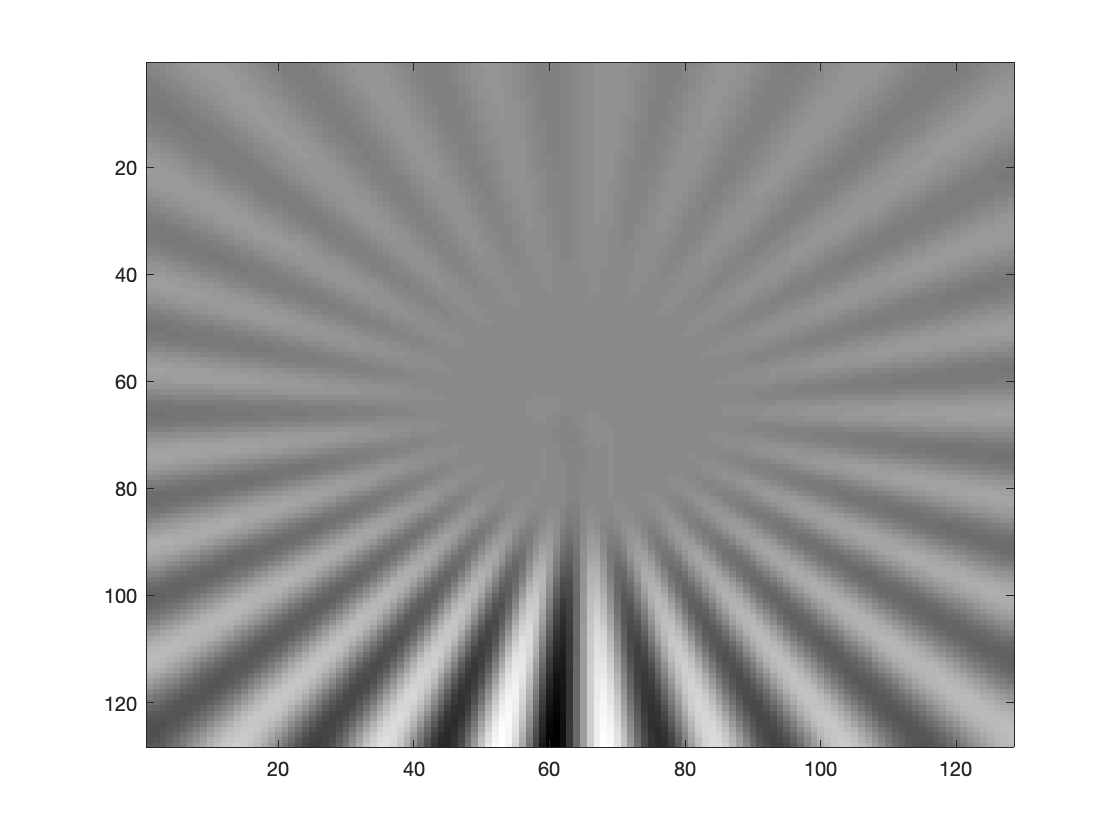

params = [1,1000,1000,-500; 0,0,1000,1000];

for param=params
    A = param(1);
    B = param(2);
    
    runRegistration(A,B)
    
end


% runRegistration2(10,2)
% runRegistration2(-10,2)


function runRegistration2(A, B)
    original = zeros(128,128);

    sd = 2; k = 4;
    correct_angle = 0.25/k;

    target = buildFan(original,correct_angle);
    target = imgaussfilt(target,sd) * A + B;
    
    figure(1);
    imagesc(target); colormap('gray');
    xlabel('x');
    ylabel('y');set(get(gca,'YLabel'),'Rotation',0);
%     title("\fontsize{14} Target Image");
    print("figures/target"+A+B+".png", '-dpng', '-r256');

    ref_img = buildFan(original,0);
    ref_img = imgaussfilt(ref_img, sd) * A + B;
    original_ref = ref_img;

    start = -0.2; stop = 0.2;
    % For every 0.0025 of a radian degree
    step_size = 0.01/4;
    thetas = start:step_size:stop;
    [metric_vals, local_max] = getMetrics(target,ref_img, thetas, A, B);

    ncc = metric_vals(1,:);
    mutual_inf = metric_vals(2,:);
    qf_dist = metric_vals(3,:);
    plot(thetas, ncc)
    hold on;
    plot(thetas, mutual_inf);
    plot(thetas, qf_dist);
    hold off;

    %Evaluating metrics
    printEvaluations(thetas, metric_vals, local_max, A, B, original_ref, correct_angle);
end